clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


simtime = 10*60;

## Control

% [param.ctrl.Ks res] = control.DesignProcedure1(param,0); 
param.ctrl.Ks = control.DesignProcedure2(param,0);

++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                Constraint|    Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality 12x12|   0.024977 to 8.0506|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                Constraint|    Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality 12x12|   0.024977 to 8.0506|
|   #2|   Matrix inequality 16x16|   0.022452 to 8.0506|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.1218
       solvertime: 0.0052
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


ans = 5.3141e-09

K = 1.0e-04 *

   -0.5594    0.1203    0.0012         0         0         0         0         0         0         0         0         0
         0         0         0   -0.4651    0.0998    0.0011         0         0         0         0         0         0
         0         0         0         0         0         0   -0.3848    0.0869    0.0010         0         0         0
         0         0         0         0         0         0         0         0         0   -0.5351    0.1135    0.0011


tau = 1.8818e+08

## Simulate decoupled system

for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode45(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);
end

## Simulate coupled system

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0,options);
coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);

## Plot simulation results

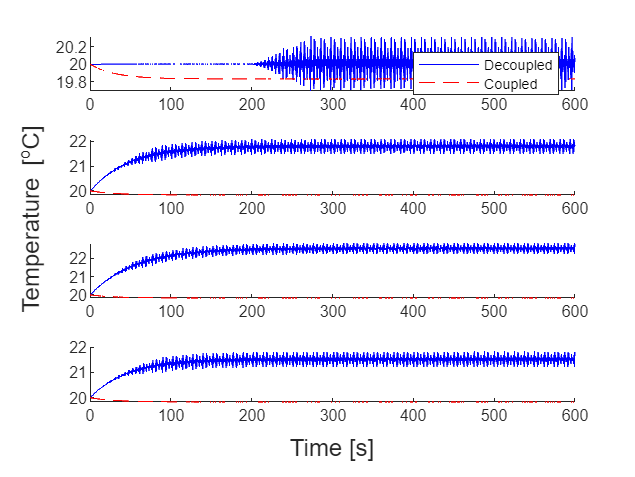

figure()
f = tiledlayout('vertical');
for i=1:4
    nexttile
    hold on
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15,'blue')
    plot(coupledResults.time,coupledResults.Ta(:,i)-273.15,['red','--'])
    if i==1
        legend('Decoupled','Coupled',Location='northeast')
    end
    hold off
end
xlabel(f,'Time [s]')
ylabel(f,'Temperature [^{o}C]')
% saveas(gcf,'../Images/Examination_Baseline_PD2','epsc')